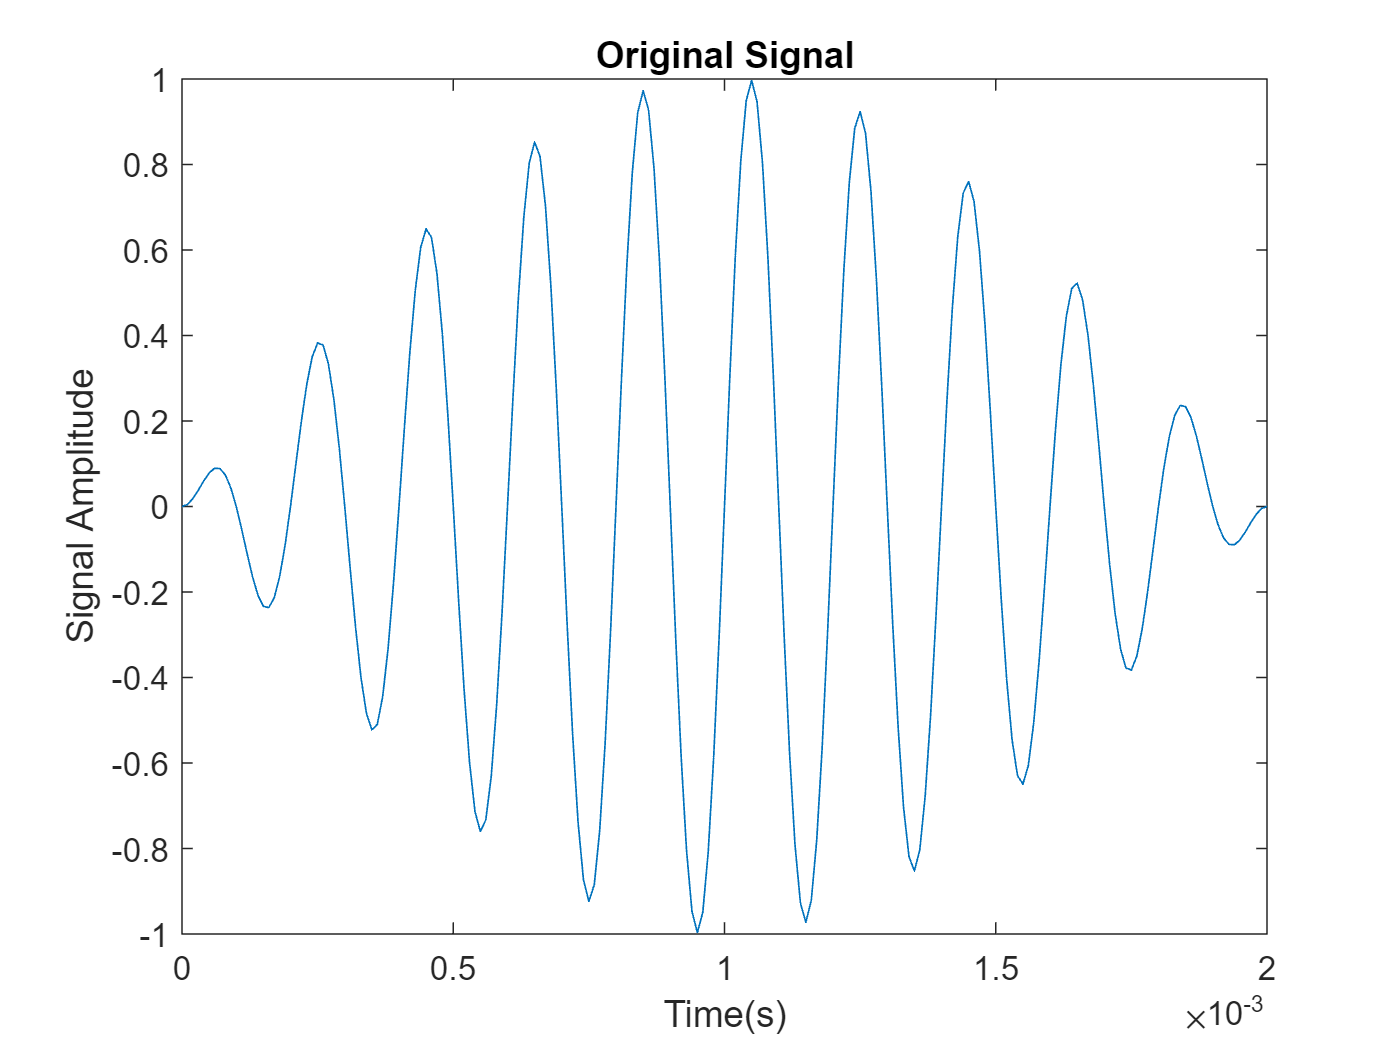

% --Setup section
    clear; clc; format compact; close all;

% --create signal
    fs = 100000;
    f = 5000;
    w = f*2*pi;
    T = 10*(1/f);
    t = 0:1/fs:T;
    amp = sin(w/20*t);
    signal = amp.*sin(w*t);
    A = randn([1,length(signal)]);

% --Display signal
    figure(1)
    plot(t, signal)
        xlabel('Time(s)')
        ylabel('Signal Amplitude')
        title('Original Signal')
        hold on

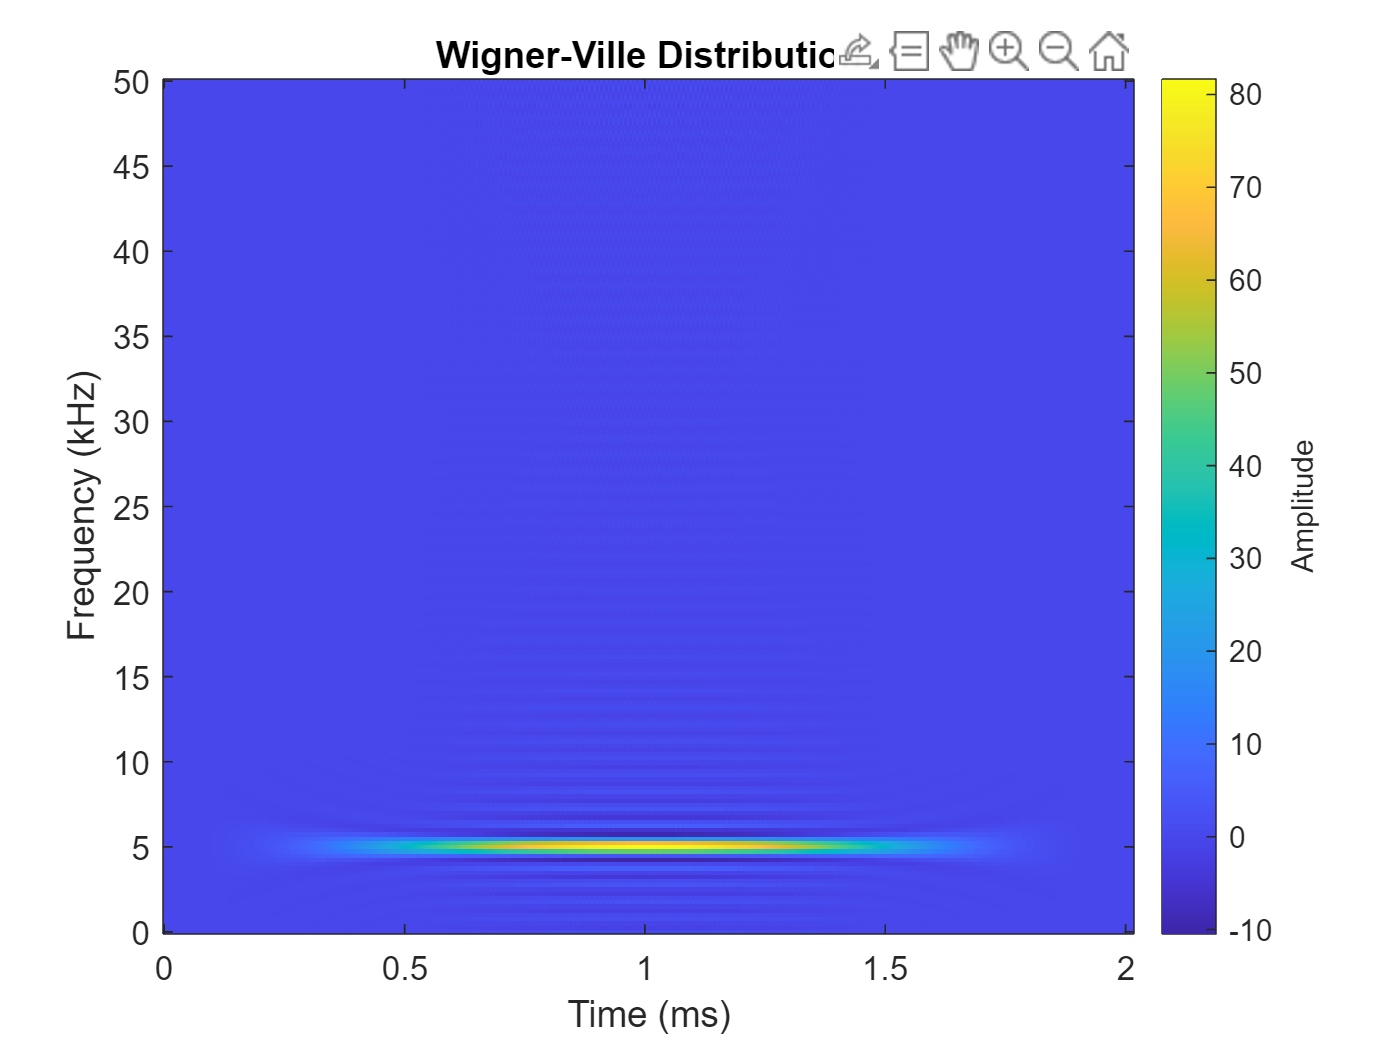


% --Perform wvd of signal
    figure(2)
    wvd(signal,fs)

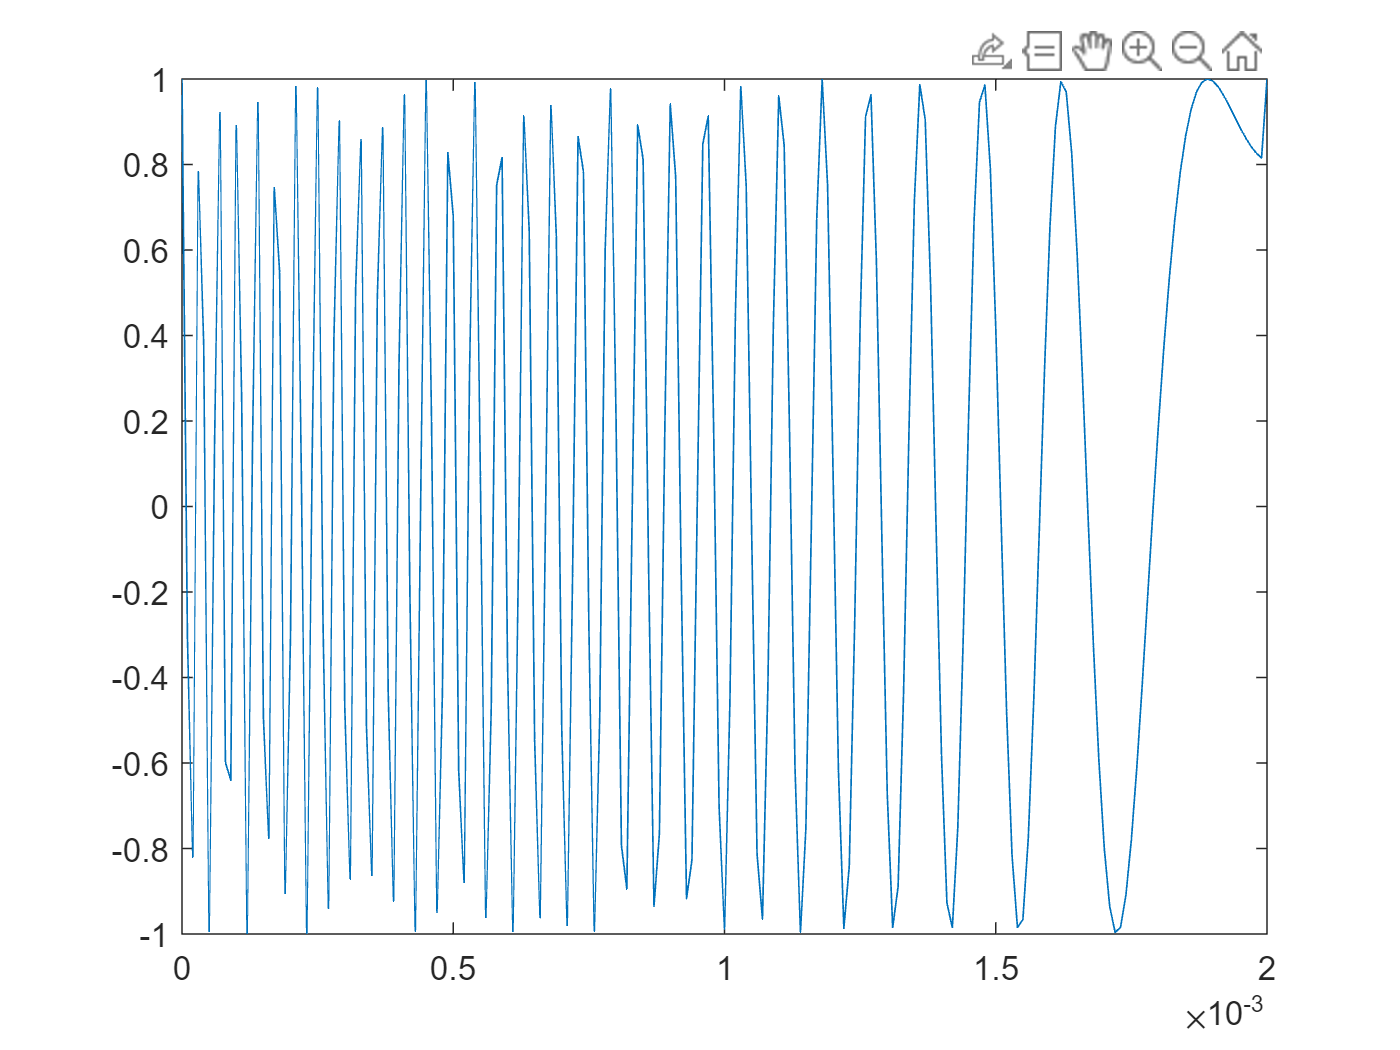


% --Create a linear chirp
    chirp = create_chirp("Linear",1,max(t),30000,100,fs,"False");
    figure(3)
    chirp = [chirp; 1];
    plot(t,chirp)

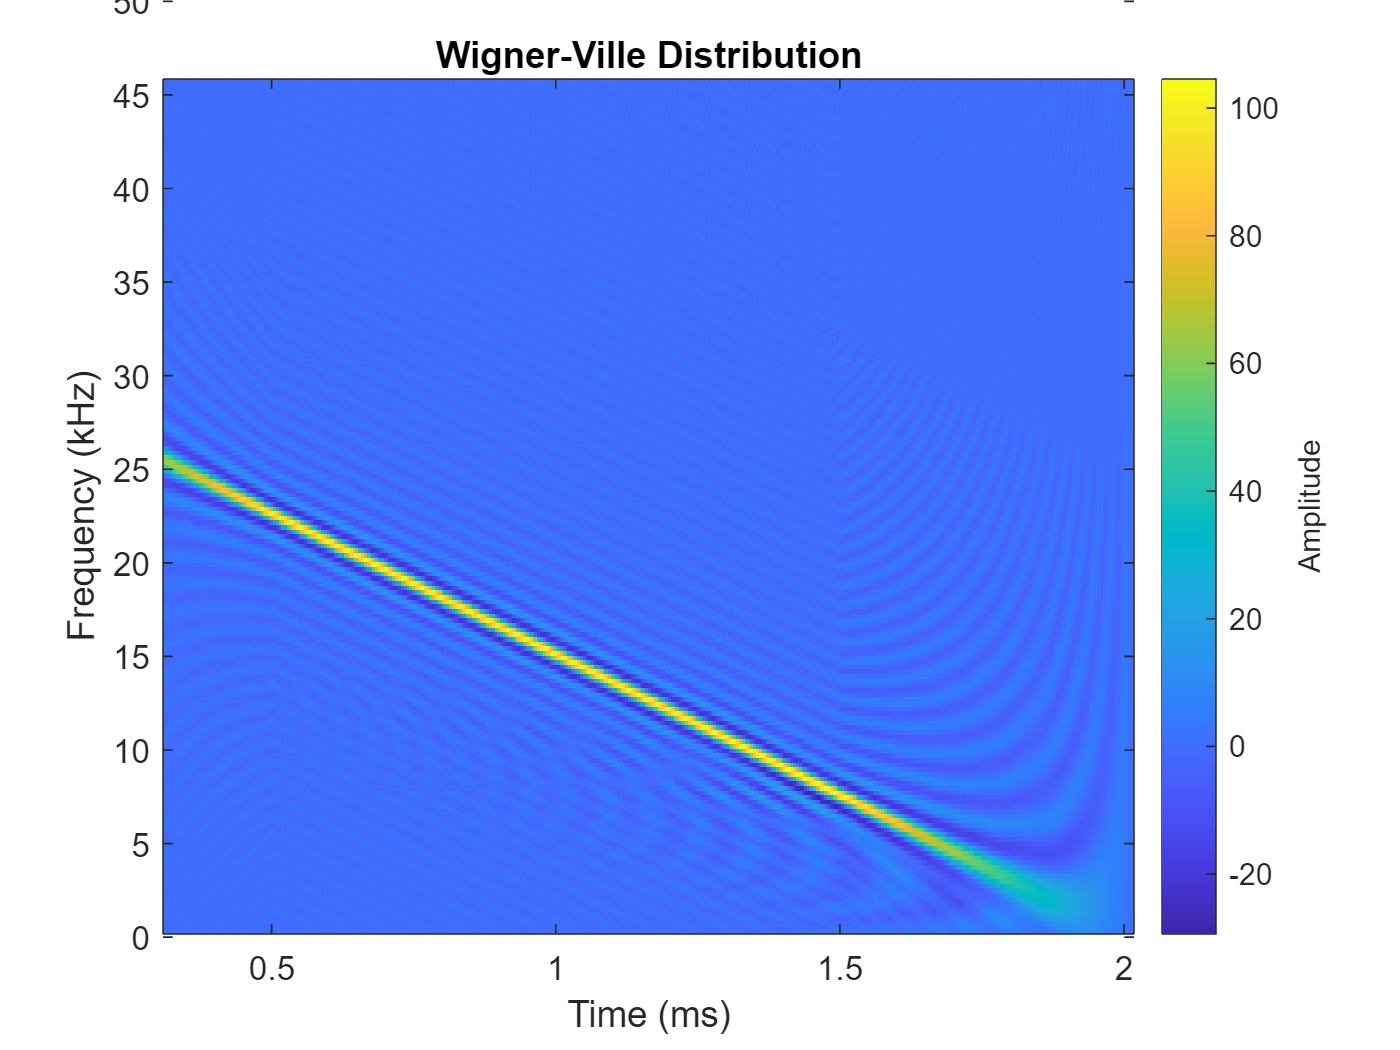


    figure(4)
    wvd(chirp,fs)

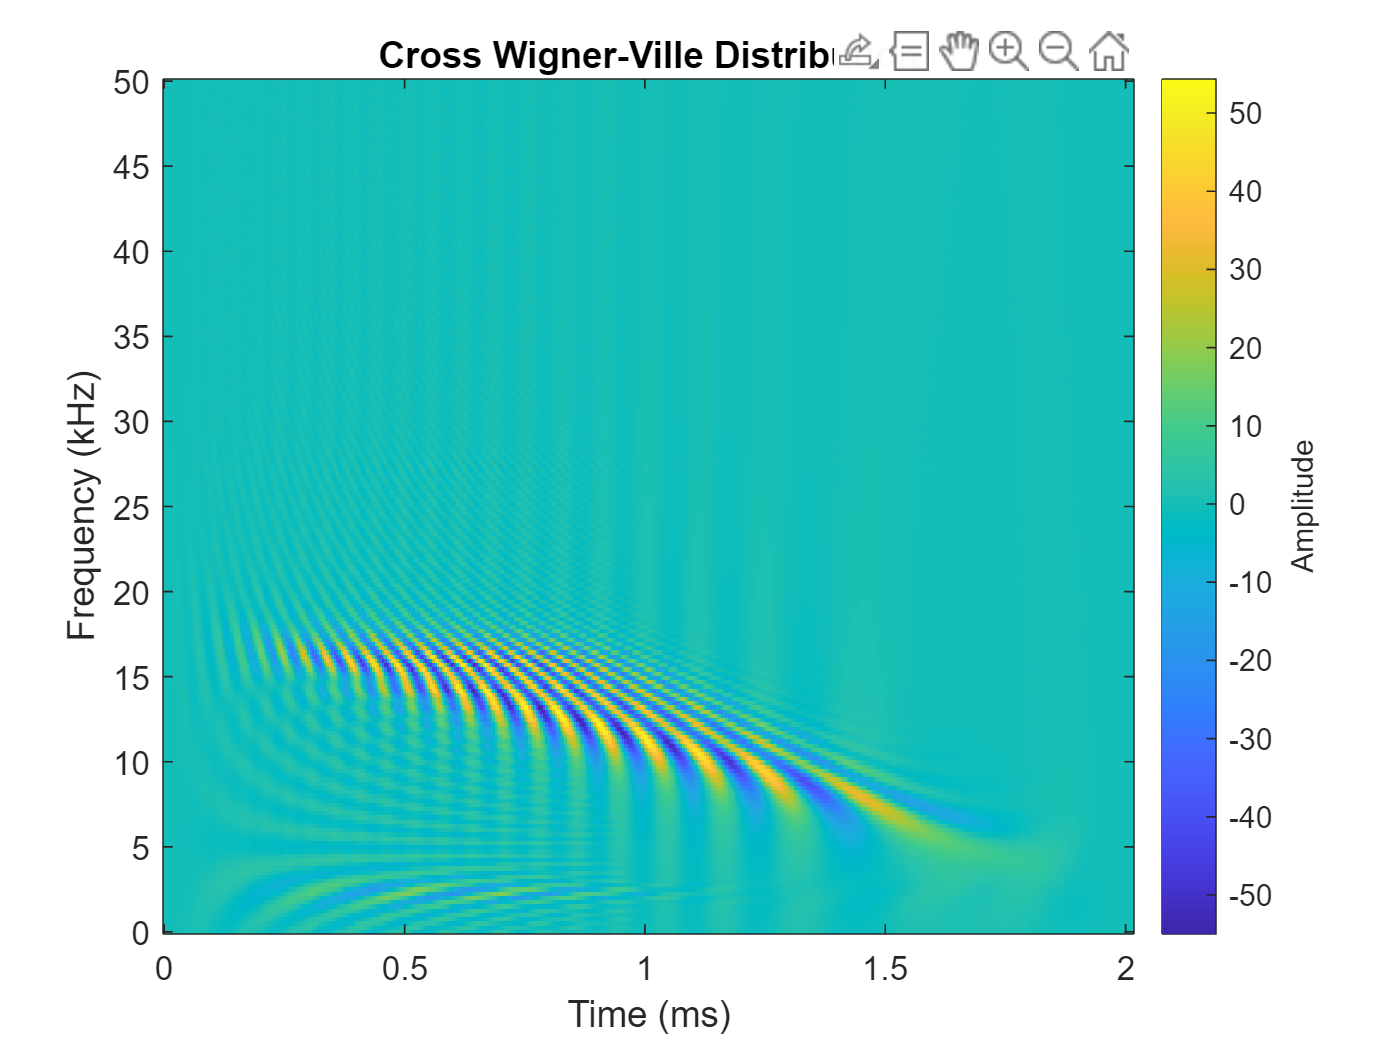


% --Cross wigner-ville
    figure()
    xwvd(signal,chirp,fs)

The xWVD of 1,2 is different than the xWVD of 2,1. The Conjugate of the xWVD 2,1 is equivalent to the xWVD_{1,2}

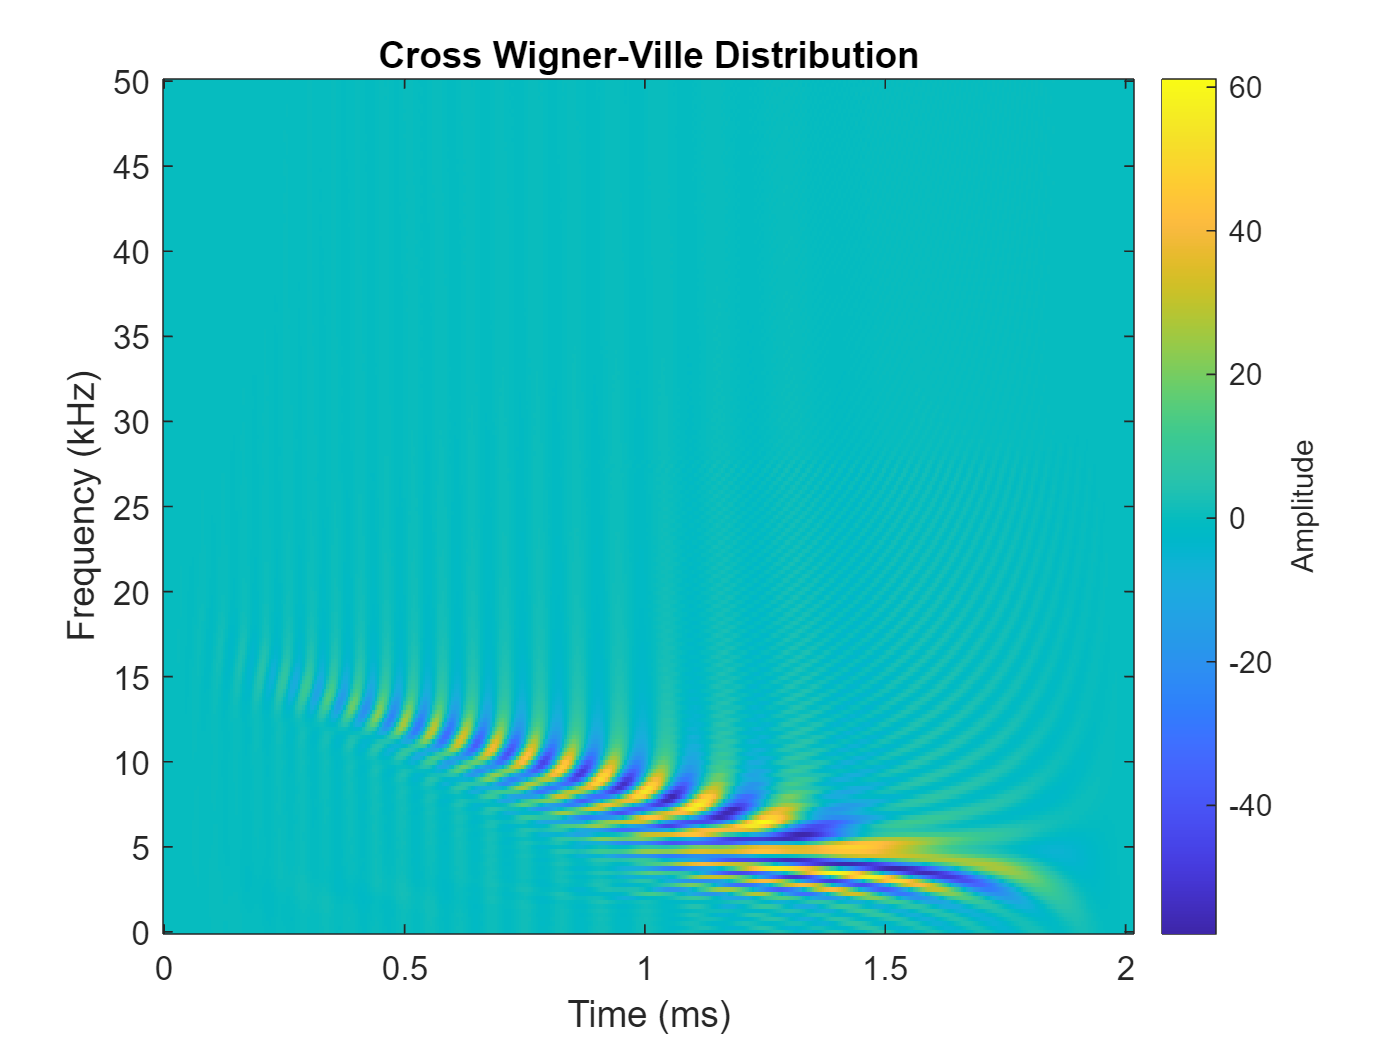

% --Inverse cross WVD
    figure()
    xwvd(chirp,signal,fs)

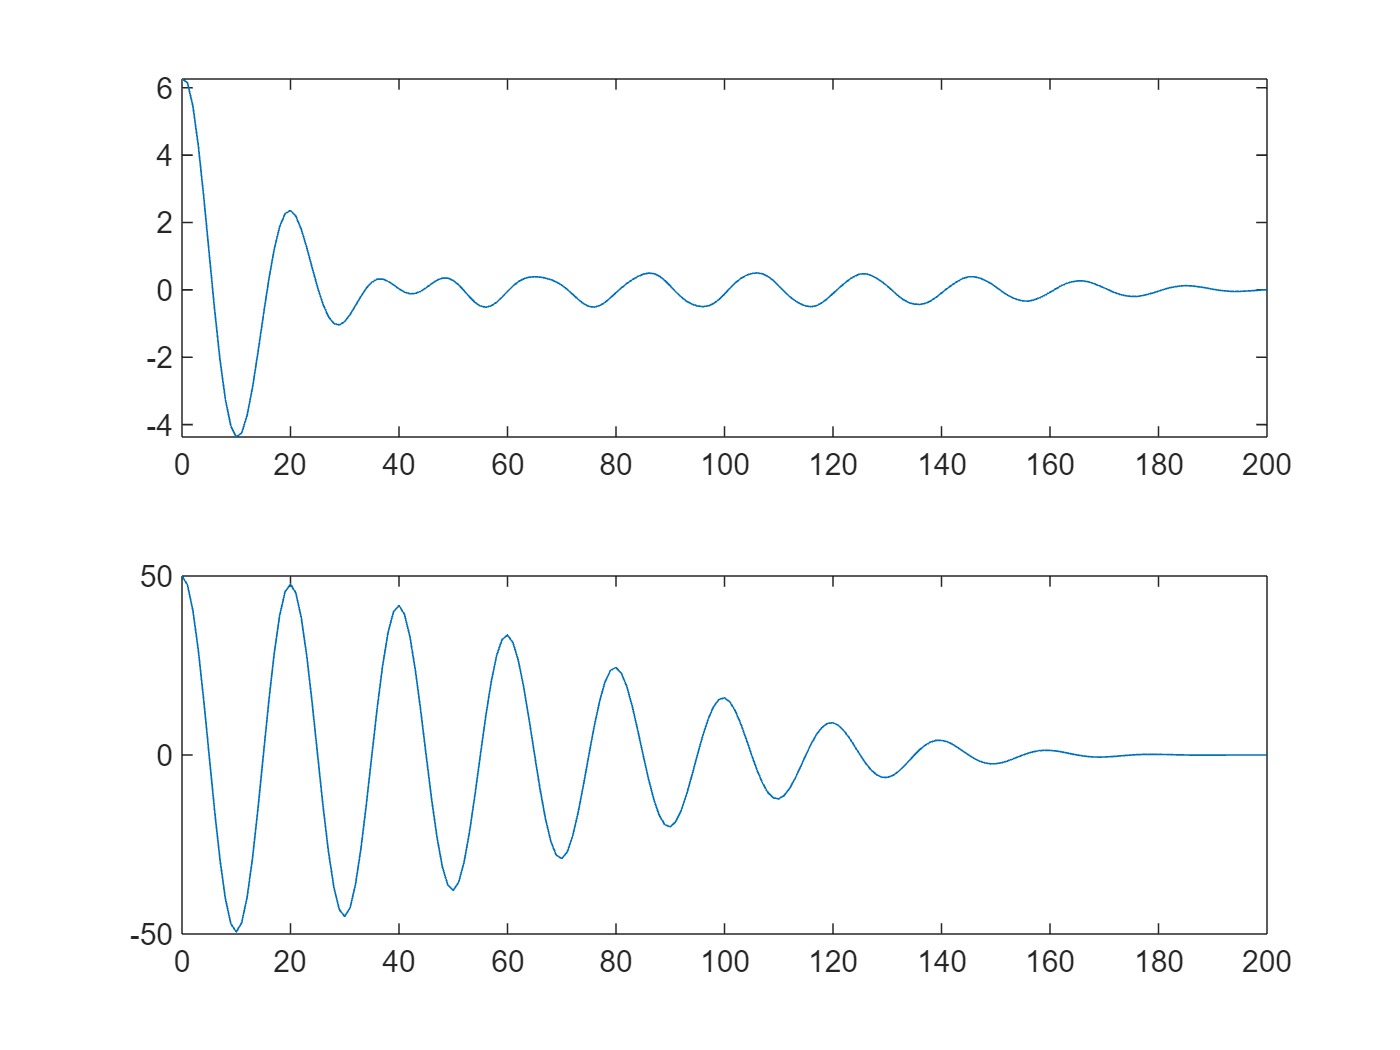


% --xcorr of the signals
    [corr, lags] = xcorr(signal,chirp);
    figure()
    subplot(2,1,1)
    plot(lags,corr)
    xlim([0 200])

    [corr, lags] = xcorr(signal);
    subplot(2,1,2)
    plot(lags,corr)
    xlim([0 200])


% --